% Importing the varibales from the workspace_1D

% Controllability matrix
C_M = [B AB A2B A3B A4B A5B]

C_M = 1.0e-03 *

         0    1.0000         0   -0.1472         0    0.1419
    1.0000         0   -0.1472         0    0.1419         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1128         0    0.1249
    0.1000         0   -0.1128         0    0.1249         0


disp("Rank of the controllability matrix =")

Rank of the controllability matrix =


disp(rank(C_M))

     6



disp("Since the rank of the controllability matrix is full, the system is the controllable")

Since the rank of the controllability matrix is full, the system is the controllable



% The initial conditions for the system are assumed as:
X0 = [10; 0; 20; 0; 30; 0];
% We assume the values of Q and R which are a part of cost function
Q = diag([50, 100, 150, 200, 250, 300])

Q =     50     0     0     0     0     0
     0   100     0     0     0     0
     0     0   150     0     0     0
     0     0     0   200     0     0
     0     0     0     0   250     0
     0     0     0     0     0   300


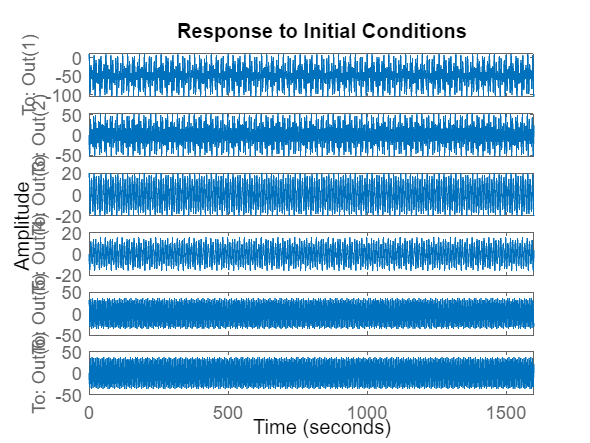

R = 0.0025;

% Assumption: C matrix is a direct representation of the output matrix, which makes D=0
C = diag([1,1,1,1,1,1]);
D = 0;

% Plot for the System_1
System_1 = ss(A,B,C,D);
figure
initial(System_1,X0)


% Finding Gain matrix, Positive definte matrix, Eigen values
[K_matrix, P_matrix, Eigen_values] = lqr(A,B,Q,R);
K_matrix

K_matrix =   141.4214  618.5136    8.9425 -407.9109  100.2355 -105.9440


P_matrix

P_matrix = 1.0e+04 *

    0.0219    0.0428   -0.0144   -0.0714   -0.0037   -0.0390
    0.0428    0.1891    0.0083   -0.3415    0.0226   -0.1742
   -0.0144    0.0083    2.0805    0.0108    0.0578   -0.0658
   -0.0714   -0.3415    0.0108    4.4473    0.0767    0.1713
   -0.0037    0.0226    0.0578    0.0767    1.3368   -0.0136
   -0.0390   -0.1742   -0.0658    0.1713   -0.0136    1.3919


Eigen_values

Eigen_values =   -0.0118 + 0.7262i
  -0.0118 - 0.7262i
  -0.0271 + 1.0403i
  -0.0271 - 1.0403i
  -0.2548 + 0.2328i
  -0.2548 - 0.2328i


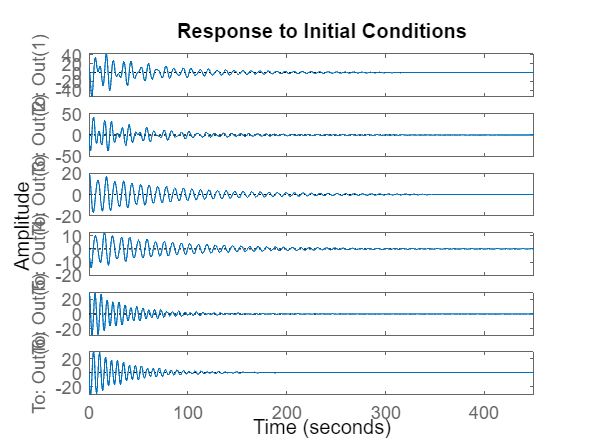

ABK = A-(B*K_matrix);

% Plot for the System_2
System_2 = ss(ABK,B,C,D);
figure
initial(System_2,X0)

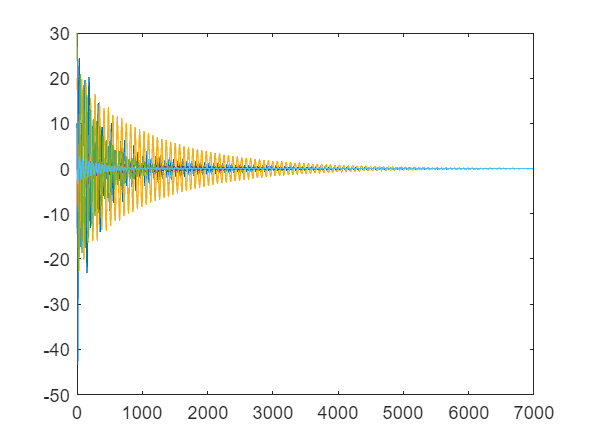

% For the original non-linear system:
X0 = [10; 0; 20; 0; 30; 0];
Timespan = 0:0.1:7000;
[T1,X1] = ode45(@LQR_controller,Timespan,X0);
% Plot the function output
plot(T1,X1)

function X_dot = LQR_controller(T1,X)
% Mass of the Crane
M= 1000;
% Load mass 1
m1= 100; 
% Load mass 2
m2= 100;
% Length of the cable for the 1st load
l1= 20; 
% Length of the cable for the 2nd load
l2= 10;
% Acceleration due to gravity
g= 9.81;
% A matrix
A=[0 1 0 0 0 0;
0 0 -(m1*g)/M 0 -(m2*g)/M 0;
0 0 0 1 0 0;
0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
0 0 0 0 0 1;
0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
% B matrix
B=[0; 
   1/M;
   0;
   1/(M*l1);
   0;
   1/(M*l2)];
% We assume the values of Q and R which are a part of cost function
Q = diag([50, 100, 150, 200, 250, 300]);
R = 0.0025;
[K_matrix] = lqr(A,B,Q,R);
F = -K_matrix*X;
X_dot = zeros(6,1);

% X(1) = x
X_dot(1) = X(2); % X_dot

% X(2) = x_dot
X_dot(2)=(F-(g/2)*(m1*sind(2*X(3))+m2*sind(2*X(5)))-(m1*l1*(X(4)^2)*sind(X(3)))-(m2*l2*(X(6)^2)*sind(X(5))))/(M+m1*((sind(X(3)))^2)+m2*((sind(X(5)))^2)); % X_Doubledot

% X(3) = Theta_1
X_dot(3)= X(4); % Theta_1 dot

% X(4) = Theta_1 dot
X_dot(4)= (X_dot(2)*cosd(X(3))-g*(sind(X(3))))/l1'; % Theta_1 Doubledot;

% X(5)= Theta_2
X_dot(5)= X(6); % Theta_2 Dot

% X(6)= Theta_2 dot;
X_dot(6)= (X_dot(2)*cosd(X(5))-g*(sind(X(5))))/l2; % Theta_2 Doubledot;
end